% Welcome fellow Matlab users! Let's just dig into Matlab!
% Refer to http://web.cecs.pdx.edu/~gerry/MATLAB/variables/matrices.html.

% This is how you can write one-line comments.

%{ 
    Multi-line comments are enclosed
    between '%{' and '%}'.
%}

% Let's create variables with basic types: integer, double, string, matrices

x = 1  % [try adding a semicolon at the end of expression to supress the output]

x = 1


x = double(102)  % [try changing to int32, uint8, char, string]

x = 102

% operations
y = 1*3 + 1/5 + 3^2 - 30 + sqrt(144) + pow2(3)

y = 2.2000

z = -2.2 + y % [why's it not zero?]

z = -8.8818e-16

% You can output variables using fprintf and/or disp built-ins.

fprintf('Scalar value (fprintf): %d', x);

Scalar value (fprintf): 102


disp(['Scalar value (disp): ', num2str(x)]);  % [type: help num2str]

Scalar value (disp): 102


% all numerical variable in Matlab are matrices (even scalars!)
[num_rows, num_cols] = size(x);
fprintf('rows: %d, cols: %d', num_rows, num_cols);

rows: 1, cols: 1

% string is an array of characters
s = 'Kazan Federal University'

s = 'Kazan Federal University'


% addressing array's elements is straight-forward
% BUT keep in mind that indexing starts from 1

s(1)   % 1st element

ans = 'K'

s(end) % last element

ans = 'y'


disp(['size: ', num2str(size(s))])

size: 1  24


% vector is a matrix with either one row or column

v = [1, 4, 2];  % row-vector
disp(v);

     1     4     2




v = [1; 4; 2];  % column-vector
disp(v);

     1
     4
     2




v = ones(1, 3);  % [replace 'ones' with 'zeros']
disp(v);

     1     1     1




v = ones(3, 1);
disp(v);

     1
     1
     1




v = linspace(1, 5, 3);  % [change 3 to other value and see the result]
disp(v);

     1     3     5



% addressing vector elements
v = randi(99, [1, 5]);
disp(v);

    65     4    85    93    68




v(1) % 1st element

ans = 65

v(size(v, 2))  % [what does size(v, 2) mean?]

ans = 68


v = randi(99, [5, 1]);
disp(v);

    76
    74
    39
    65
    17




v(1)

ans = 76

v(size(v, 1))

ans = 17

% colon notation helps to refer to ranges of elements
x_begin = 1;
x_end = 5;
x_step = 2;  % [set x_step to other values]

v = x_begin:x_end;  % step is 1 by default
disp(v);

     1     2     3     4     5




v = x_begin:x_step:x_end;
disp(v);

     1     3     5



% slices
v = 1:2:10;
disp(v);

     1     3     5     7     9




disp(v(1:2:3));

     1     5




disp(v(3:-1:1)); % [TASK] output in reverse order using slices

     5     3     1



% vector operations
v1 = [1, 0, 0];
v2 = [0, 1, 0];

disp(v1);

     1     0     0




disp(v1 + 2) % addition of a scalar

     3     2     2



disp(v1 * 2) % multiplication by a scalar

     2     0     0




disp(v1 - v2); % vector subtraction

     1    -1     0




disp(dot(v1, v2)) % dot product

     0



disp(cross(v1, v2))

     0     0     1




disp(v1') % transpose

     1
     0
     0




disp(v1' * v1) % column-vector to row-vector multiplication

     1     0     0
     0     0     0
     0     0     0



% creating matrices
A = [1, 2; 3, 4]

A =      1     2
     3     4



A = [1:2; 3:4]

A =      1     2
     3     4



% addressing elements
A(1, 1)

ans = 1

A(2, 1)

ans = 3


A(1, :) % all columns at 1st row

ans =      1     2


A(:, 1) % all rows at 1st column

ans =      1
     3



A(:) % all elements expanded in column-wise order

ans =      1
     3
     2
     4


% matrix operations
A = [1, 2; 2 3]

A =      1     2
     2     3



inv(A)

ans =    -3.0000    2.0000
    2.0000   -1.0000



A * inv(A)

ans =      1     0
     0     1



inv(A) * A

ans =      1     0
     0     1



det(A)

ans = -1


% skew-symmetric matrix (from a vector)
skew([1 2 3])

ans =      0    -3     2
     3     0    -1
    -2     1     0



% transpose
A'

ans =      1     2
     2     3



% augmenting
[A, [5; 5]]

ans =      1     2     5
     2     3     5



[A; [5, 5]]

ans =      1     2
     2     3
     5     5



B = ones(2, 2)

B =      1     1
     1     1



% matrix multiplication
A * B 

ans =      3     3
     5     5



% element-wise multiplication
A .* B

ans =      1     2
     2     3



% filtering
v = 1:7

v =      1     2     3     4     5     6     7


v(v > 3)

ans =      4     5     6     7


A = [1 2 0; 2 5 -1; 4 10 -1]

A =      1     2     0
     2     5    -1
     4    10    -1



eig(A) % eigen values

ans =     3.7321
    0.2679
    1.0000



svd(A)

ans =    12.3171
    0.5149
    0.1577


% complex numbers
complex(1, 2)

ans = 1.0000 + 2.0000i


complex(1, 2) + complex(0, -1)

ans = 1.0000 + 1.0000i


complex(1, 2) * complex(2, 1)

ans = 0.0000 + 5.0000i


complex(1, 3) / complex(1, 1)

ans = 2.0000 + 1.0000i


abs(complex(3, 4))  % magnitude

ans = 5


rad2deg(angle(complex(cos(pi/3), sin(pi/3))))

ans = 60.0000

% loops, conditions, etc.
A = int8(ones(3, 2))

A = 3×2 int8 matrix
   1   1
   1   1
   1   1



for i=1:size(A, 1)
    for j=1:size(A, 2)
        fprintf('row: %d, col: %d, value: %d\n', i, j, A(i, j));
        
        if mod(i, 2) == 0
            disp('Even')
        end
    end
end

row: 1, col: 1, value: 1
row: 1, col: 2, value: 1
row: 2, col: 1, value: 1


Even


row: 2, col: 2, value: 1


Even


row: 3, col: 1, value: 1
row: 3, col: 2, value: 1


% custom functions (declare at the end of the file or in separate files)
ret_val = my_function(3);

Out = 5

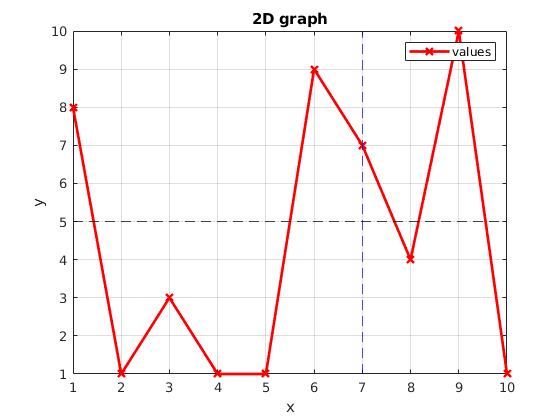

% Plotting
xs = 1:10;
ys = randi(10, [1, size(xs, 2)]);

% plot 2D graph
plot(xs, ys, 'r-x', 'LineWidth', 2);

hold on; % put on hold current figure

% horizontal line
yline(5, 'k--');

% vertical line
xline(7, 'b--');

% main title
title('2D graph');

% 2D grid
grid("on");

% axis labels
xlabel('x')
ylabel('y');

% legend
legend(['values'])

hold off;  % release current figure

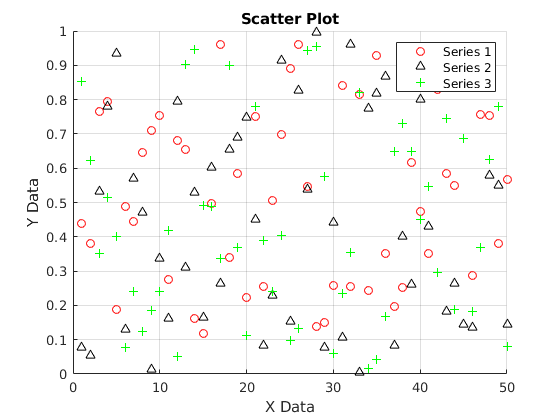

xs = 1:50;
ys1 = rand([1, size(xs, 2)]);
ys2 = rand([1, size(xs, 2)]);
ys3 = rand([1, size(xs, 2)]);

scatter(xs, ys1, 'ro');

hold on;

scatter(xs, ys2, 'k^');
scatter(xs, ys3, 'g+');

title('Scatter Plot');
xlabel('X Data');
ylabel('Y Data');
grid("on");

legend({'Series 1', 'Series 2', 'Series 3'})

hold off;

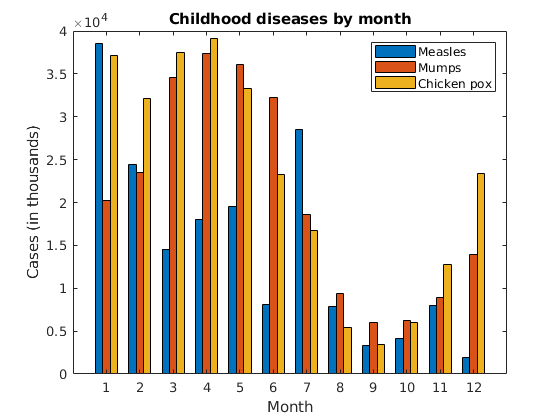

% Create data for childhood disease cases
measles = [38556 24472 14556 18060 19549 8122 28541 7880 3283 4135 7953 1884];
mumps = [20178 23536 34561 37395 36072 32237 18597 9408 6005 6268 8963 13882];
chickenPox = [37140 32169 37533 39103 33244 23269 16737 5411 3435 6052 12825 23332];

% Create a vertical bar chart using the bar function
figure
bar(1:12, [measles' mumps' chickenPox'], 1)

% Set the axis limits
axis([0 13 0 40000])

set(gca, 'XTick', 1:12)

% Add title and axis labels
title('Childhood diseases by month')
xlabel('Month')
ylabel('Cases (in thousands)')

% Add a legend
legend('Measles', 'Mumps', 'Chicken pox')

% 1. Generate a sequence of numbers S from 1 to 100 with step k = (1, 3, 5)
% 2. Plot a Gaussian bell curve witn mean = 0, variance = 1
% 3. Create a 2D matrix A of size M x N. Compute row-wise and column-wise sum and product of elements.
% 4. Find min and max values of A. Find min and max elements per column/row
% 5. Plot f(x) = |sin(x^3)| and g(x) = cos(x)^2 on the same graph, -2*pi <
% x < 2*pi (with different colors, markers). Add graph legend, axis labels, title.

function Out = my_function(Input)
    Out = Input + 2
end